## Análisis del puente Golden Gate

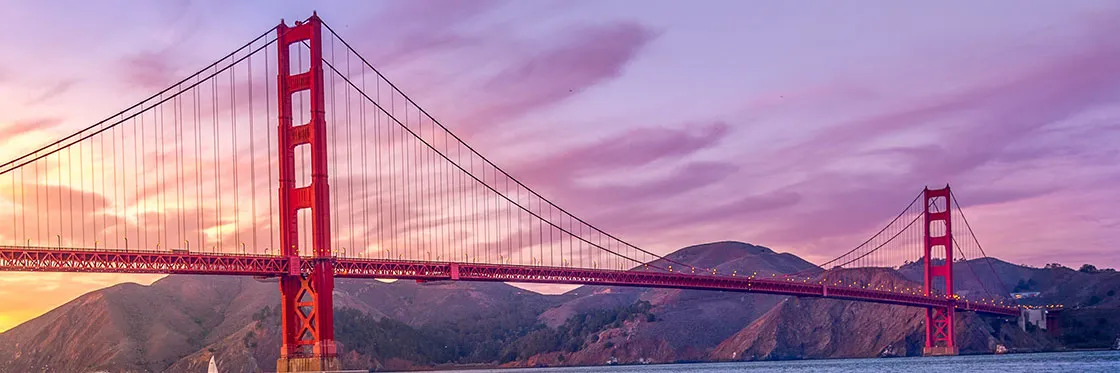

Factor de conversión

meters = 0.305 % pies a metros

meters = 0.3050

centimeters = 30.48 % pies a centimetros

centimeters = 30.4800

Inches = 12 % pies a pulgadas

Inches = 12

F = 1

F = 1

Datos importantes

% Número de nodos en el cable principal
N = 250

N = 250

% Separación horizontal de los cables verticales (ft)
li = 50*F

li = 50

% Maxima distancia entre el punto más bajo y más alto del cable principal
MAX_CABLE_SAG = 472.2*F

MAX_CABLE_SAG = 472.2000

% Longitud del cable principal
LENGTH_MAIN_SPAN = 4200*F

LENGTH_MAIN_SPAN = 4200

% Fueza horizontal de cada cable (kips)
H = 53467 

H = 53467

% Peso (kips/ft)
W = 3.35

W = 3.3500

Ecuación de la catenaria

y = @(x)-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))

y = function_handle with value:
    @(x)-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))


Aproximación

x = [0 LENGTH_MAIN_SPAN/2 LENGTH_MAIN_SPAN]

x =            0        2100        4200


y = [MAX_CABLE_SAG 0 MAX_CABLE_SAG]

y =   472.2000         0  472.2000


p2 = polyfit(x, y, 2)

p2 =     0.0001   -0.4497  472.2000


yl2 = polyval(p2, 0) - polyval(p2, li)

yl2 = 22.2180

f = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)

f = function_handle with value:
    @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)


xx = linspace(0.2, 0.5)

xx =     0.2000    0.2030    0.2061    0.2091    0.2121    0.2152    0.2182    0.2212    0.2242    0.2273    0.2303    0.2333    0.2364    0.2394    0.2424    0.2455    0.2485    0.2515    0.2545    0.2576    0.2606    0.2636    0.2667    0.2697    0.2727    0.2758    0.2788    0.2818    0.2848    0.2879    0.2909    0.2939    0.2970    0.3000    0.3030    0.3061    0.3091    0.3121    0.3152    0.3182    0.3212    0.3242    0.3273    0.3303    0.3333    0.3364    0.3394    0.3424    0.3455    0.3485


yy = f(xx)

yy =   -12.2311  -12.0765  -11.9219  -11.7672  -11.6123  -11.4574  -11.3024  -11.1472  -10.9920  -10.8366  -10.6812  -10.5256  -10.3700  -10.2142  -10.0584   -9.9024   -9.7463   -9.5900   -9.4337   -9.2773   -9.1207   -8.9640   -8.8072   -8.6503   -8.4932   -8.3360   -8.1787   -8.0213   -7.8637   -7.7060   -7.5482   -7.3902   -7.2321   -7.0739   -6.9155   -6.7570   -6.5983   -6.4395   -6.2805   -6.1214   -5.9622   -5.8028   -5.6432   -5.4835   -5.3237   -5.1637   -5.0035   -4.8432   -4.6827   -4.5221


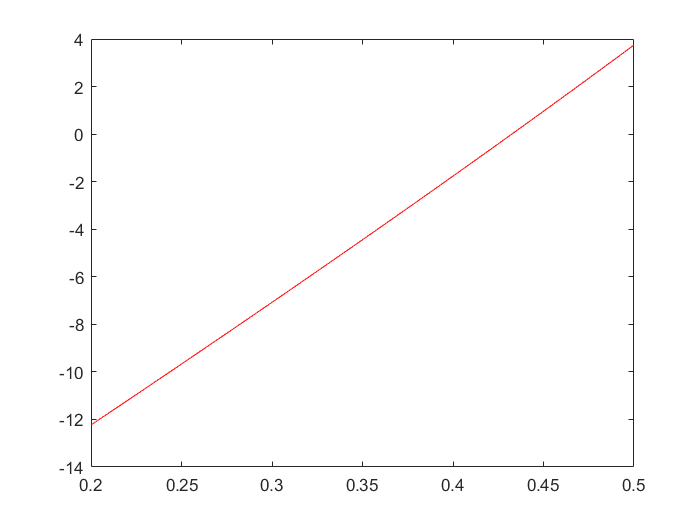

plot(xx, yy, 'r')

biseccion(f, 0.4, 0.5, 40)

ans = 41×8 table
    Iter       a          b          c          f(a)          f(b)          f(c)          error   
    ____    _______    _______    _______    ___________    _________    ___________    __________

      0         0.4        0.5       0.45         -1.765       3.7485        0.96273          0.05
      1         0.4       0.45      0.425         -1.765      0.96273       -0.40798         0.025
      2       0.425       0.45     0.4375       -0.40798      0.96273        0.27562        0.0125
      3       0.425     0.4375    0.43125       -0.40798      0.27562      -0.066611       0.00625
      4     0.43125     0.4375    0.43438      -0.066611      0.27562         0.1044      0.003125
      5     0.431

ans =          0    0.4000    0.5000    0.4500   -1.7650    3.7485    0.9627    0.0500
    1.0000    0.4000    0.4500    0.4250   -1.7650    0.9627   -0.4080    0.0250
    2.0000    0.4250    0.4500    0.4375   -0.4080    0.9627    0.2756    0.0125
    3.0000    0.4250    0.4375    0.4313   -0.4080    0.2756   -0.0666    0.0062
    4.0000    0.4313    0.4375    0.4344   -0.0666    0.2756    0.1044    0.0031
    5.0000    0.4313    0.4344    0.4328   -0.0666    0.1044    0.0189    0.0016
    6.0000    0.4313    0.4328    0.4320   -0.0666    0.0189   -0.0239    0.0008
    7.0000    0.4320    0.4328    0.4324   -0.0239    0.0189   -0.0025    0.0004
    8.0000    0.4324    0.4328    0.4326   -0.0025    0.0189    0.0082    0.0002
    9.0000    0.4324    0.4326    0.4325   -0.0025    0.0082    0.0028    0.0001


a1 = 0.4324

a1 = 0.4324

yl2 = polyval(p2, li) - polyval(p2, 2*li)

yl2 = 21.6827

f = @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)

f = function_handle with value:
    @(x)(-(H/W)*(cosh(-(W/H)*li+x)-cosh(x))-yl2)


xx = linspace(0.2, 0.5)

xx =     0.2000    0.2030    0.2061    0.2091    0.2121    0.2152    0.2182    0.2212    0.2242    0.2273    0.2303    0.2333    0.2364    0.2394    0.2424    0.2455    0.2485    0.2515    0.2545    0.2576    0.2606    0.2636    0.2667    0.2697    0.2727    0.2758    0.2788    0.2818    0.2848    0.2879    0.2909    0.2939    0.2970    0.3000    0.3030    0.3061    0.3091    0.3121    0.3152    0.3182    0.3212    0.3242    0.3273    0.3303    0.3333    0.3364    0.3394    0.3424    0.3455    0.3485


yy = f(xx)

yy =   -11.6957  -11.5412  -11.3865  -11.2318  -11.0769  -10.9220  -10.7670  -10.6118  -10.4566  -10.3013  -10.1458   -9.9903   -9.8346   -9.6789   -9.5230   -9.3670   -9.2109   -9.0547   -8.8983   -8.7419   -8.5853   -8.4286   -8.2718   -8.1149   -7.9578   -7.8007   -7.6433   -7.4859   -7.3283   -7.1706   -7.0128   -6.8548   -6.6967   -6.5385   -6.3801   -6.2216   -6.0629   -5.9041   -5.7452   -5.5861   -5.4268   -5.2674   -5.1079   -4.9482   -4.7883   -4.6283   -4.4681   -4.3078   -4.1473   -3.9867


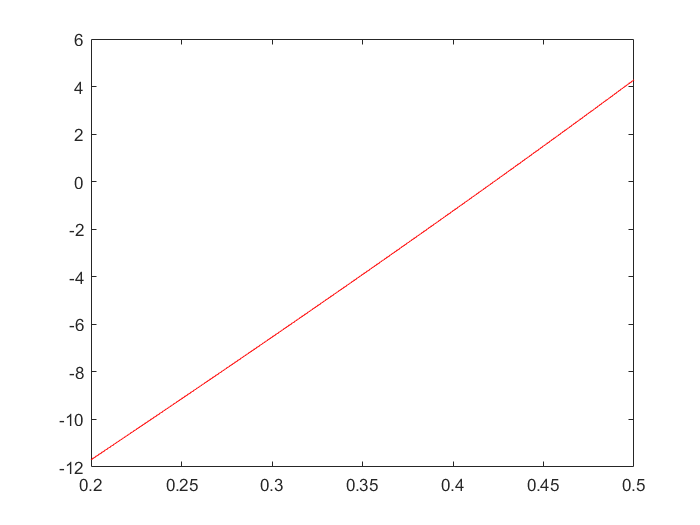

plot(xx, yy, 'r')

biseccion(f, 0.4, 0.5, 40)

ans = 41×8 table
    Iter       a          b          c          f(a)           f(b)          f(c)          error   
    ____    _______    _______    _______    ___________    __________    ___________    __________

      0         0.4        0.5       0.45        -1.2297        4.2838         1.4981          0.05
      1         0.4       0.45      0.425        -1.2297        1.4981         0.1274         0.025
      2         0.4      0.425     0.4125        -1.2297        0.1274       -0.55279        0.0125
      3      0.4125      0.425    0.41875       -0.55279        0.1274       -0.21311       0.00625
      4     0.41875      0.425    0.42188       -0.21311        0.1274      -0.042963      0.003125
      5   

ans =          0    0.4000    0.5000    0.4500   -1.2297    4.2838    1.4981    0.0500
    1.0000    0.4000    0.4500    0.4250   -1.2297    1.4981    0.1274    0.0250
    2.0000    0.4000    0.4250    0.4125   -1.2297    0.1274   -0.5528    0.0125
    3.0000    0.4125    0.4250    0.4188   -0.5528    0.1274   -0.2131    0.0063
    4.0000    0.4188    0.4250    0.4219   -0.2131    0.1274   -0.0430    0.0031
    5.0000    0.4219    0.4250    0.4234   -0.0430    0.1274    0.0422    0.0016
    6.0000    0.4219    0.4234    0.4227   -0.0430    0.0422   -0.0004    0.0008
    7.0000    0.4227    0.4234    0.4230   -0.0004    0.0422    0.0209    0.0004
    8.0000    0.4227    0.4230    0.4229   -0.0004    0.0209    0.0103    0.0002
    9.0000    0.4227    0.4229    0.4228   -0.0004    0.0103    0.0049    0.0001


a2 = 0.4227

a2 = 0.4227

%g = @(l)(-(H/W)*(cosh(-(W/H)*l+a1)-cosh(a1)))
%g(50)
P = @(l) (H*(sinh((-W/H)*l + a1) - sinh(a2)))

P = function_handle with value:
    @(l)(H*(sinh((-W/H)*l+a1)-sinh(a2)))


P(50)

ans = 383.4736

function z = biseccion(f, a, b, Maxiter)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [0 a b c f(a) f(b) f(c) error];
    for k=1:Maxiter
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        c = (a+b)/2;
        error=(b-a)/2;
        z = [z; k a b c f(a) f(b) f(c) error];
    end
    array2table(z, "VariableNames", ["Iter", "a", "b", "c", "f(a)", "f(b)", "f(c)", "error"])
end

Newton 

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = inline(subs(df),'x');
    z = [x0];
    error = 1;
    while error>Tol
        x1 = x0-f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end